# **Problem Set 2**

### **COURSE: **TIP7200 - DIGITAL SIGNAL PROCESSING

### INSTRUCTOR: ANDRE LIMA FERRER ALMEIDA

### ID NUMBER: 544957

#### PROBLEM 1 - Load the file "bipsIN.wav" in MATLAB. Plot the signal in the time and frequency domain. Conclude about the analyzed signal. Detail its response. Write the mathematical expression of the present the x[n] signal and its Fourier transform expression X($e^{j\omega}
$).

First of all, the audio data is loaded into workspace and played using the following commands:

clc; clear all; close all;

[x,Fs] = audioread("bipsIN.wav");
sound(x);

where **x** is the vector data in time domain and *Fs* is its sampling rate. The response of x[n] in the time domain is plotted bellow:

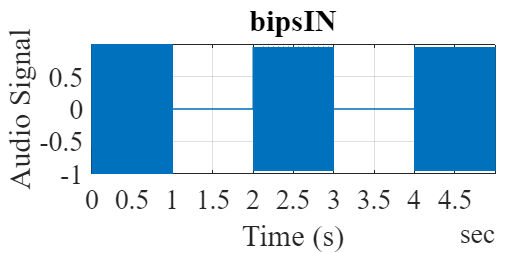

t = 0:seconds(1/Fs):seconds(length(x)/Fs);
t = t(1:end-1);

fig = figure; clf

plot(t,x); hold on
grid on
plotlatex(fig,'bipsIN', 'Time (s)', 'Audio Signal');
hold off

It is easy to observe that the audio signal is periodic. So, it can be represented as sum of discrete-time sinusoids and as consequence there is an integer period N > 0 such that:


$$x[n] = x[n +N]$$


if $x[n] = A cos(\omega_0 n+\phi)
$, then:


$$N = \frac{2\pi k}{\Omega}$$


where $k\in \mathbb{Z}$. In face of this statements, x[n] can be describe as


$$x[n] = 0.999969cos(\omega_{1} n + \phi_1 ) + 0.952911cos(\omega_{2} n + \phi_2 ) + 0.952911cos(\omega_{3} n + \phi_3 )  $$


To better identify the frequency of each wave and its initial phase shift (taking the origin as the reference point) is important to analyze the signal spectrum. Thus, to visualize its response in the frequency domain it is calculated the FFT of the present signal using the MATLAB function fft() which computes the discrete Fourier transform (DFT) of x using a fast Fourier transform (FFT) algorithm:

X = fft(x);
x_fft = fftshift(X);
L = length(x);

The frequency response of x[n] is plotted bellow:

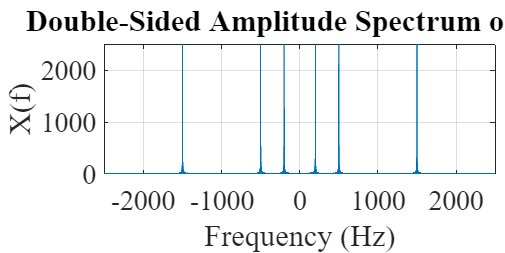

f = Fs*(-L/2:L/2-1)/L;

fig = figure; clf

plot(f,abs(x_fft)); hold on
grid on
plotlatex(fig,'Double-Sided Amplitude Spectrum of X(f)', ...
    'Frequency (Hz)', 'X(f)');
hold off

As expected, the spectrum response of the present signal is symmetric taking the y-axis as the reference point. Thus, it is possible to analyze the signal response by looking at the positive side of the spectrum. The single-sided spectrum of X[f] is plotted as it follows:

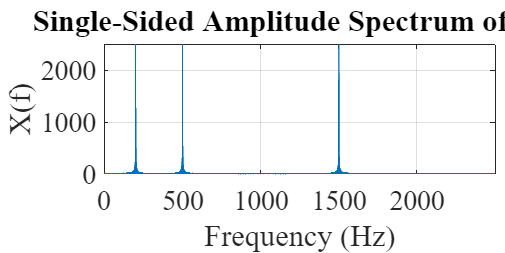

x_ffts = x_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(x_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of X(f)', ...
    'Frequency (Hz)', 'X(f)');
hold off

Combining the information present in the time and frequency domain, note that $f_{1}=200 Hz$, $f_{2}=500 Hz$ e $f_{3}=1500 Hz$. To find the angular frequency, the frequency is multiplied by $2\pi$. As for the initial phase shift of each signal, the angular frequency is multiplied by the k position the signal starts. Therefore,

phi2 = 2*pi*500*(10000)

phi2 = 3.1416e+07

phi3 = 2*pi*1500*(20000)

phi3 = 1.8850e+08

For the the case of the first signal, as it starts a 0 and the cosine function is the one selecte to represent it, the initial phase shift is 90° or 1.57 [rad]. So, x[n] can mathematically represented as:

omega1 = 2*pi*200

omega1 = 1.2566e+03

omega2 = 2*pi*500

omega2 = 3.1416e+03

omega3 = 2*pi*1500

omega3 = 9.4248e+03


$$x[n] = 0.999969cos(2\pi(200) n + 1.57) + 0.952911cos(2\pi(500) n + 3.14\cdot10^{7} ) +\\ 0.952911cos(2\pi(1500) n + 1.88\cdot10^{8} )  $$


Since the Fourier Transform of the cosine function is


$$\mathcal{F}\{cos(\omega_0n+\phi)\}=\sum_{k=-\infty}^{\infty}[\pi e^{j\phi}\delta(\omega-\omega_0 +2\pi k)+\pi e^{-j\phi}\delta(\omega+\omega_0 +2\pi k)]$$


the frequency response $X(e^{j\omega})$ of x[n] is


$$X(e^{j\omega})=0.999969\sum_{k=-\infty}^{\infty}[\pi e^{j1.57}\delta(\omega-1.26\cdot10^3 +2\pi k)+\pi e^{-j1.57}\delta(\omega+1.26\cdot10^3 +2\pi k)]+ \\

0.952911\sum_{k=-\infty}^{\infty}[\pi e^{j3.14\cdot10^{7}}\delta(\omega-3.14\cdot10^3 +2\pi k)+\pi e^{-j3.14\cdot10^{7}}\delta(\omega+3.14\cdot10^3 +2\pi k)]+\\

0.952911\sum_{k=-\infty}^{\infty}[\pi e^{j1.88\cdot10^{8}}\delta(\omega-9.42\cdot10^3 +2\pi k)+\pi e^{-j1.88\cdot10^{8}}\delta(\omega+9.42\cdot10^3 +2\pi k)]$$


#### PROBLEM 2 - Now, load the file "bipsOUT.wav" in MATLAB. Plot the signal response in the time and frequency domain. What is possible to conclude about the present signal compared with the one in the previous problem? What is possible to conclude about this system knowing the output signal "bipsOUT.wav" is resulted by the input signal "bipsIN.wav", in particular, about its frequency response? Implement a LTI system with such ouput response as the one observed in "bipsOUT.wav" (or a equivalent one) considering "bipsIN.wav" the input signal. Plot the impulse and the frequency response of the chosen system.

Now, loading the audio data "bipsOUT.wav" into workspace and plotting both time and frequency response (looking at the positive side of the spectrum) of y[n]

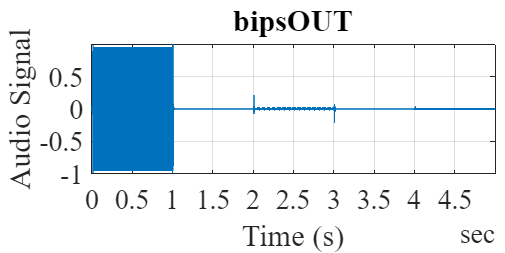

[y,Fs] = audioread("bipsOUT.wav");
sound(y);

t = 0:seconds(1/Fs):seconds(length(y)/Fs);
t = t(1:end-1);

fig = figure; clf

plot(t,y); hold on
grid on
plotlatex(fig,'bipsOUT', 'Time (s)', 'Audio Signal');
hold off

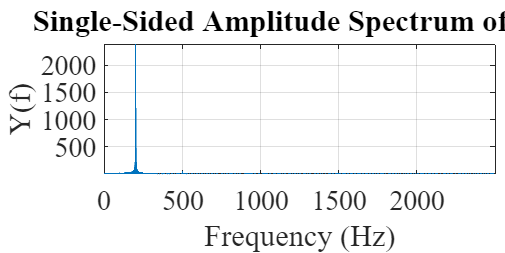


L = length(y);
Y = fft(y);
y_fft = fftshift(Y);
y_ffts = y_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(y_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of Y(f)', ...
    'Frequency (Hz)', 'Y(f)');
hold off

Assuming that the currently analyzed signal is the response of a Linear Time-Invariant (LTI) system to the input signal 'bipsIN', it is evident that the system affects the higher frequency components in such a manner that they become inaudible and visually imperceptible on the plots. 

This observation suggests that the system is likely acting as a low-pass filter, which is designed to attenuate or eliminate signals with frequencies higher than its cutoff frequency. An ideal low-pass filter is characterized by

where, $\omega_c$ is the cutoff frequency. Thus, the reponse y[n] of an LTI system h[n] to a input x[n] is defined as


$$y[n] = h[n]*x[x]$$


Applying the Fourier Transform, then


$$Y(e^{j\omega})=H(e^{j\omega})X(e^{j\omega})
$$


To show the system sugest is an alternative to obtain a similiar behavior as the one by 'bipsOUT', the MATLAB function lowpass() is used

f_cut = 200;
lw_pass = lowpass(x,f_cut,Fs);

Given the range of possibilities for the cutoff frequency, a specific value of 200 Hz was selected. The resulting filter output signal is plotted below, confirming that this choice provides one possible characterization of the LTI system.

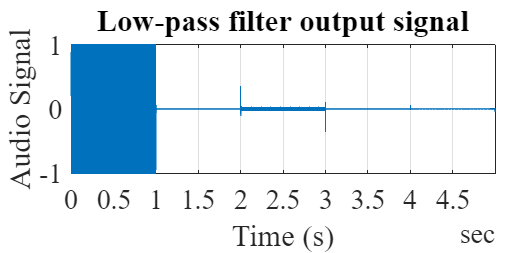

fig = figure; clf

plot(t,lw_pass); hold on
grid on
plotlatex(fig,'Low-pass filter output signal', 'Time (s)', ...
    'Audio Signal');
hold off

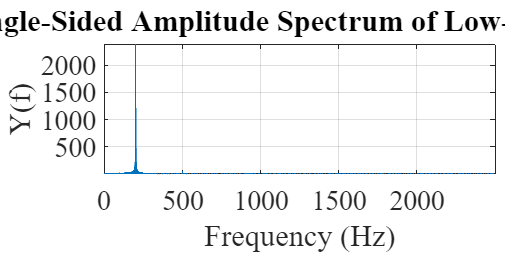


L = length(lw_pass);
LW = fft(lw_pass);
lw_fft = fftshift(LW);
lw_ffts = y_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(lw_ffts)); hold on
grid on
plotlatex(fig,['Single-Sided Amplitude Spectrum of Low-pass ' ...
    'filter'], 'Frequency (Hz)', 'Y(f)');
hold off

#### PROBLEM 3 - Repeat the steps from the problems 1 and 2 using the audio signals "bipsIN-mixed.wav" and "bipsOUT-mixed.wav". What is possible to observe in the new results compared to the previous ones?

Doing the previous steps to the signals "bipsIN_mixed.wav" and "bipsOUT_mixed.wav". Firstly, the time and frequency response of the former are plotted

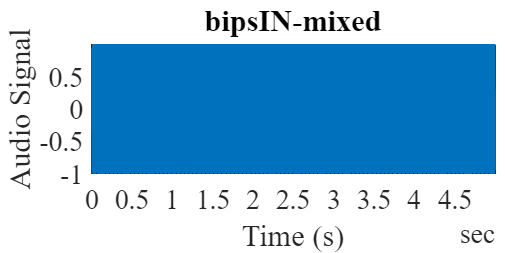

clc; clear all; close all;

[x,Fs] = audioread("bipsIN_mixed.wav");

t = 0:seconds(1/Fs):seconds(length(x)/Fs);
t = t(1:end-1);

fig = figure; clf

plot(t,x); hold on
grid on
plotlatex(fig,'bipsIN-mixed', 'Time (s)', 'Audio Signal');
hold off

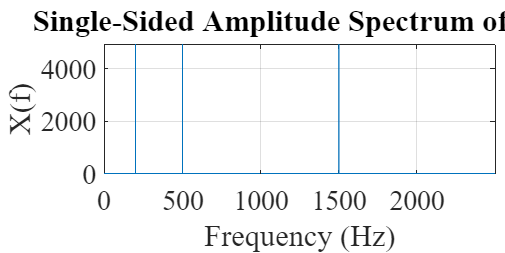


X = fft(x);
x_fft = fftshift(X);
L = length(x);

x_ffts = x_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(x_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of X(f)', ...
    'Frequency (Hz)', 'X(f)');
hold off

Following the same procedure for the signal "bipsOUT_mixed.wav", the time-domain and frequency-domain behaviors can be observed as follows

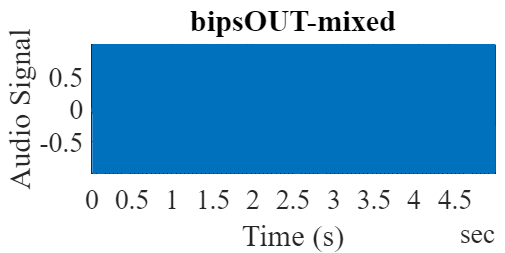

[y,Fs] = audioread("bipsOUT_mixed.wav");

t = 0:seconds(1/Fs):seconds(length(y)/Fs);
t = t(1:end-1);

fig = figure; clf

plot(t,y); hold on
grid on
plotlatex(fig,'bipsOUT-mixed', 'Time (s)', 'Audio Signal');
hold off

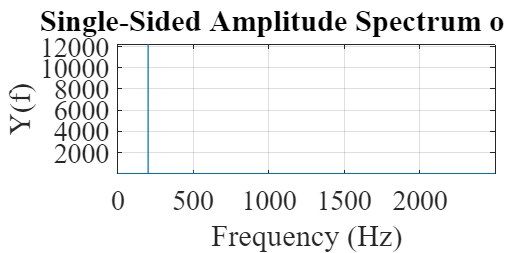


L = length(y);
Y = fft(y);
y_fft = fftshift(Y);
y_ffts = y_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(y_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of Y(f)', ...
    'Frequency (Hz)', 'Y(f)');
hold off

It is evident that the behavior of the system remains consistent regardless of the signals occurring at different time instants or simultaneously. The system exhibits the characteristic of attenuating the frequency components of the signals that exceed a certain threshold. This behavior is in line with the expectations of a Linear Time-Invariant (LTI) system that adheres to the superposition theorem.

Hence, if the same low-pass filter that was suggested as a possible representation of the system is applied to the "bipsIN_mixed.wav" signal, it will be expected the output of the filter to exhibit similar characteristics to those observed in the "bipsOUT_mixed.wav" signal. This implies that the filter would attenuate the frequency components of "bipsIN_mixed.wav" that exceed the cutoff frequency, resulting in a filtered output with a similar frequency response as "bipsOUT_mixed.wav".

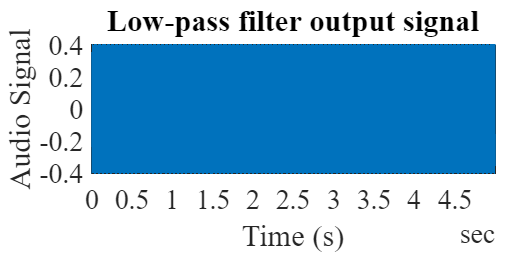

f_cut = 200;
lw_pass = lowpass(x,f_cut,Fs);

fig = figure; clf

plot(t,lw_pass); hold on
grid on
plotlatex(fig,'Low-pass filter output signal', 'Time (s)', ...
    'Audio Signal');
hold off

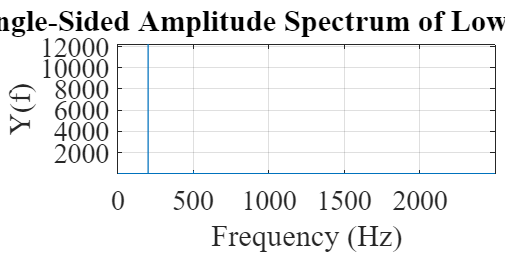


L = length(lw_pass);
LW = fft(lw_pass);
lw_fft = fftshift(LW);
lw_ffts = y_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(lw_ffts)); hold on
grid on
plotlatex(fig,['Single-Sided Amplitude Spectrum of Low-pass ' ...
    'filter'], 'Frequency (Hz)', 'Y(f)');
hold off

As anticipated, the output signal demonstrated a similar behavior to that of the "bipsOUT_mixed.wav" signal, providing further confirmation that it can effectively represent the underlying Linear Time-Invariant (LTI) system to which the input signals were subjected. This supports the hypothesis that the system can be accurately characterized as a low-pass filter.

#### PROBLEM 4 - Load the file "bomdia.wav" and "bomdia-reverb.wav" in MATLAB. Plot both the time and frequency domain signals. Listen to both audio signals. What can be conclude when we compare the plots time/frequency of these signals and their sound quality? Now, load the file "imp-resp.mat" and plot its impulse response h[n]. Generate the output signal of this system assuming "bomdia.wav" as the input signal. Compare the result with "bomdia-reverb.wav" signal. What is possible to conclude?

Firstly, the audio data "bomdia.wav" is loaded into workspace and the played using the sound function. Then, the time and frequency response of the are plotted bellow

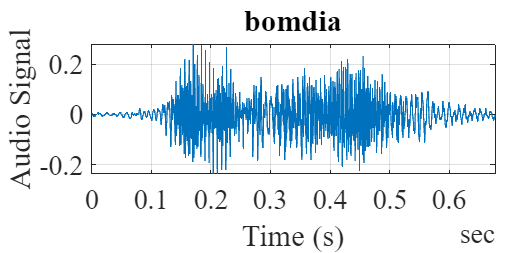

clc; clear all; close all;

[x,Fs] = audioread("bomdia.wav");
sound(x);

t = 0:seconds(1/Fs):seconds(length(x)/Fs);
t = t(1:end-1);

fig = figure; clf

plot(t,x); hold on
grid on
plotlatex(fig,'bomdia', 'Time (s)', 'Audio Signal');
hold off

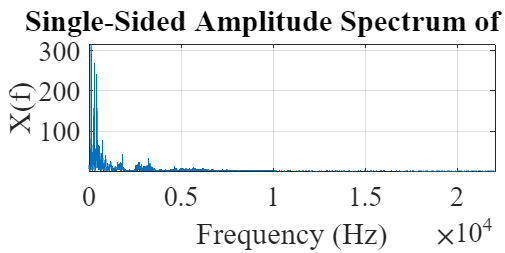


X = fft(x);
x_fft = fftshift(X);
L = length(x);

x_ffts = x_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(x_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of X(f)', ...
    'Frequency (Hz)', 'X(f)');
hold off

The same procedures are repeated to "bomdia-reverb.wav". The time-domain and frequency-domain behaviors can be observed as follows

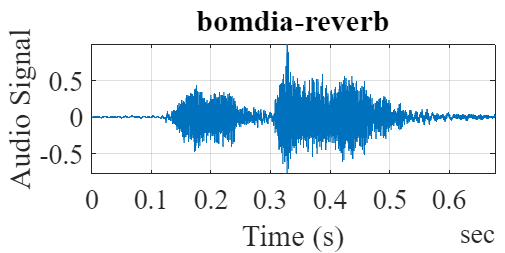

[y,Fs] = audioread("bomdia_reverb.wav");
sound(y);

t = 0:seconds(1/Fs):seconds(length(y)/Fs);
t = t(1:end-1);

fig = figure; clf

plot(t,y); hold on
grid on
plotlatex(fig,'bomdia-reverb', 'Time (s)', 'Audio Signal');
hold off

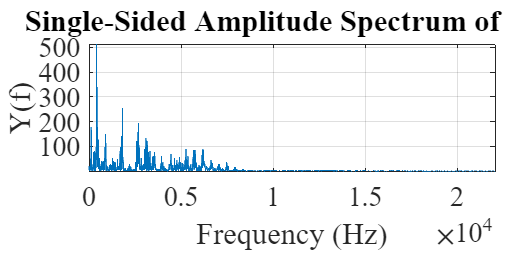


L = length(y);
Y = fft(y);
y_fft = fftshift(Y);
y_ffts = y_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(y_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of Y(f)', ...
    'Frequency (Hz)', 'Y(f)');
hold off

By comparing the time-domain responses and the audibility of the signals, notable differences can be observed. The first signal, "bomdia," exhibits frequency components with high energy that are concentrated in lower frequencies. This observation aligns with the perception of the sound, as it has a prominent bass presence and a visibly wave-shaped waveform in the time-domain plot.

On the other hand, the "bomdia-reverb" signal displays a more dispersed distribution of frequency components across the spectrum. It demonstrates a higher energy density in the higher frequency range, resulting in a sound with a higher pitch compared to the "bomdia" signal. Consequently, the waveform of the "bomdia-reverb" signal appears more intricate and less visually discernible compared to the "bomdia" waveform.

These findings highlight the distinct spectral characteristics and perceptual qualities of the two signals, emphasizing the impact of frequency distribution on sound perception and waveform visualization.

The LTI system impulse response, denoted as h[n], was imported into the workspace, and its behavior is graphically depicted below

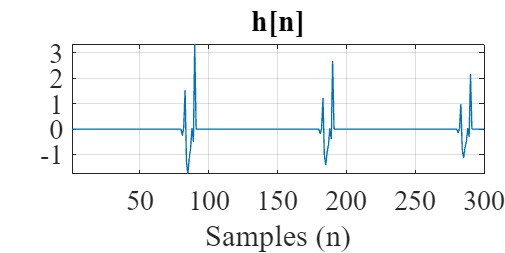

h = load("imp_resp.mat");
h = struct2array(h);

fig = figure; clf

plot(h); hold on
grid on
plotlatex(fig,'h[n]', 'Samples (n)', ' ');
hold off

To obtain the system response to the input signal "bomdia" the convolution sum is performed. The resulting output signal, denoted as y1[n], is computed using the conv() function and is presented in the plot below

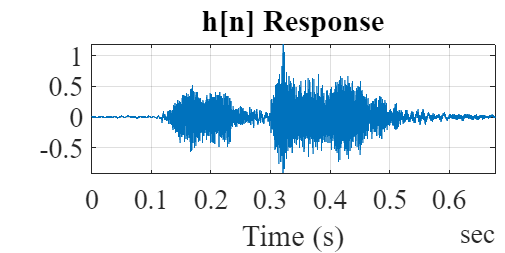

y1 = conv(x,h);
L1 = length(y1)-length(x);
y1 = y1(L1+1:end);

sound(y1);

t = 0:seconds(1/Fs):seconds(length(x)/Fs);
t = t(1:end-1);

fig = figure; clf

plot(t,y1); hold on
grid on
plotlatex(fig,'h[n] Response', 'Time (s)', ' ');
hold off

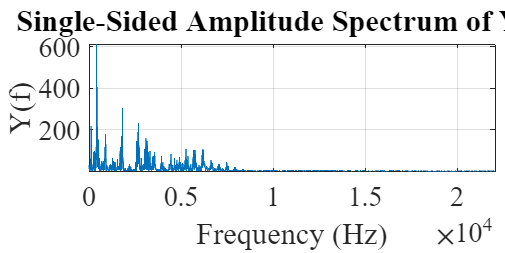


L = length(y1);
Y1 = fft(y1);
y1_fft = fftshift(Y1);
y1_ffts = y1_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(y1_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of Yh(f)', ...
    'Frequency (Hz)', 'Y(f)');
hold off

The similarity between the system response and the "bomdia-reverb" signal is evident, indicating that the system itself is responsible for generating the "bomdia-reverb" signal as its response to the "bomdia" input signal.

#### PROBLEM 5 - The Figure below shows a possible solution to restore the original signal "bomdia.wav" from the "bomdia-reverb.wav" (which is a distorted version of the original signal) using a system called "equalizer".

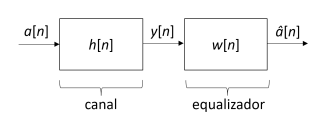

#### Consider a[n] as the original signal ("bomdia.wav") and y[n] as the distorted one ("bomdia-reverb.wav"). Determine a solution for the impulse response of the "equalizer" system w[n]. Next, obtain the "equalized" signal â[n] and compare it with the original one. What can be concluded? Also, calculate the approximation error defined as error = $\sum_{n=1}^{N}\left \| a[n]-\hat{a}[n] \right \|^{2}$.

Let $H(e^{j\omega})$ represent the Fourier Transform of the system impulse response h[n]. In order to design a system that can cancel out the influence of the original system on the signal and mitigate the resulting distortion, a new system w[n] needs to be implemented. The goal is to find a w[n] that satisfies the equation:

$w[n] * h[n] = \delta [n]$,

Applying the Z-transform


$$W(e^{j\omega})H(e^{j\omega})=1\\
W(e^{j\omega}) = \frac{1}{H(e^{j\omega})}$$


By achieving this condition, the output of the new system w[n] when driven by the distorted signal will ideally yield a signal that is free from the effects of the original system. That system is defined as the inverse system and is denoted as $H_i(e^{j\omega})$. 

Therefore, 

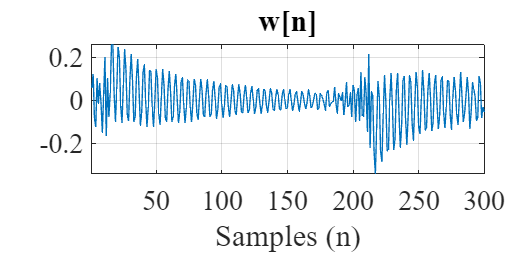

h = load("imp_resp.mat");
h = struct2array(h);

H = fft(h);
W = 1./H;
w = ifft(W);

fig = figure; clf

plot(w); hold on
grid on
plotlatex(fig,'w[n]', 'Samples (n)', ' ');
hold off

Assuming "bomdia" (a[n]) as the input signal to h[n], and "bomdia-reverb" (y[n]) as the output of h[n] and the input to w[n], the new signal â[n] can be calculated by performing the convolution sum between w[n] and y[n]

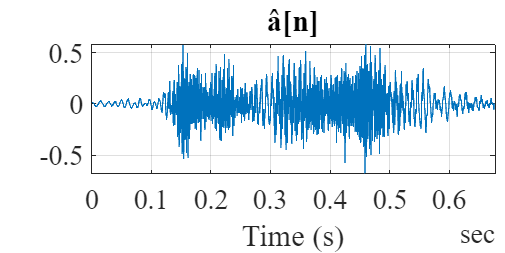

[x,Fs] = audioread("bomdia.wav");
[y,Fs] = audioread("bomdia_reverb.wav");

t = 0:seconds(1/Fs):seconds(length(x)/Fs);
t = t(1:end-1);

a_est = conv(y,w);
La = length(a_est)-length(y);
a_est = a_est(La+1:end);

fig = figure; clf

plot(t,a_est); hold on
grid on
plotlatex(fig,'â[n]', 'Time (s)', ' ');
hold off

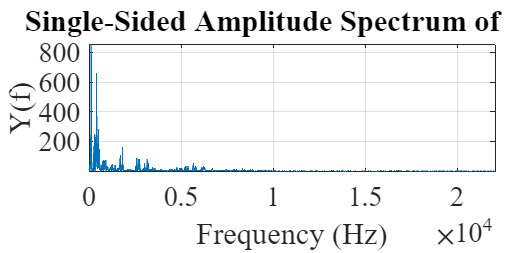


L = length(a_est);
A_fft = fft(a_est);
a_est_fft = fftshift(A_fft);
a_est_ffts = a_est_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(a_est_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of Â(f)', ...
    'Frequency (Hz)', 'Y(f)');
hold off

Computing the approximation error

err = (abs(a_est-x)).^2;

mean(err)

ans = 0.0164

var(err)

ans = 9.3190e-04

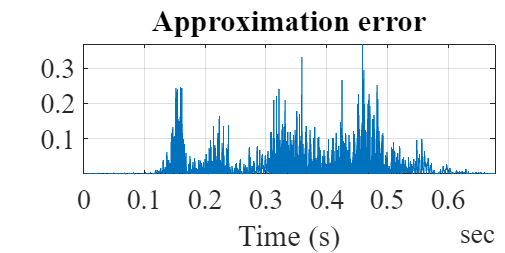


fig = figure; clf

plot(t,err); hold on
grid on
plotlatex(fig,'Approximation error', 'Time (s)', ' ');
hold off

Despite strictly adhering to the definition, it is evident that the estimation of the signal "bomdia" was not achieved perfectly. This resulted in an approximation error with a mean value of approximately two decimal places and a variance of approximately three decimal places. Furthermore, the frequency response of the estimated signal exhibited significant differences compared to the original "bomdia" signal. However, the time-domain signal and overall shape of the frequency response displayed some similarities to the original signal.

#### PROBLEM 6 - Load the file "preamble.wav" in MATLAB. Plot its impulse and frequency response. Obtain the output signal y[n] using the impulse response "imp-resp.mat" which models the distorted system h[n] from the above figure. Save the information as "preamble-reverb.wav". Next, following the figure steps, develop an equalizer w[n] and obtain an equalized signal. Plot its frequency response and verify the result of the resulting signal. Discuss the result collected.

Loading the audio data "preamble.wav" into workspace and plotting both time and frequency response (looking at the positive side of the spectrum) of x[n]

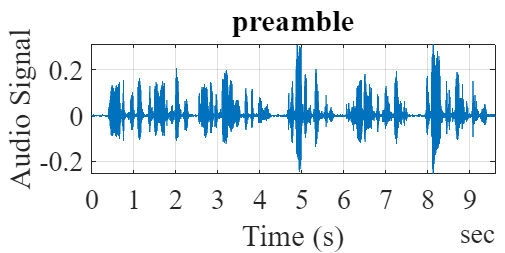

clc; clear all; close all;

[x,Fs] = audioread("preamble.wav");
sound(x);

t = 0:seconds(1/Fs):seconds(length(x)/Fs);
t = t(1:end-1);

fig = figure; clf

plot(t,x); hold on
grid on
plotlatex(fig,'preamble', 'Time (s)', 'Audio Signal');
hold off

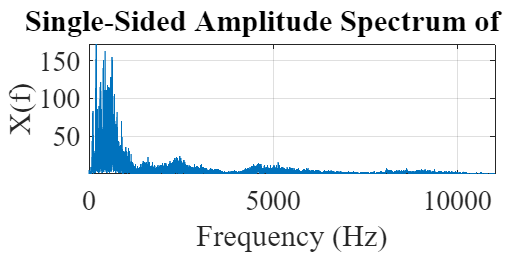


X = fft(x);
x_fft = fftshift(X);
L = length(x);

x_ffts = x_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(x_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of X(f)', ...
    'Frequency (Hz)', 'X(f)');
hold off

The LTI system impulse response, denoted as h[n], was imported into the workspace, and its behavior is graphically depicted below

h = load("imp_resp.mat");
h = struct2array(h);

fig = figure; clf

plot(h); hold on
grid on
plotlatex(fig,'h[n]', 'Samples (n)', ' ');
hold off

To obtain the system response to the input signal "preamble" the convolution sum is performed. The resulting output signal, denoted as y1[n], is computed using the conv() function and is presented in the plot below

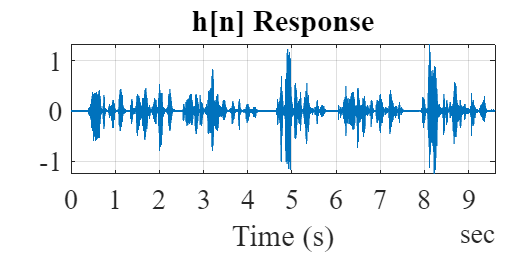

y1 = conv(x,h);
L1 = length(y1)-length(x);
y1 = y1(L1+1:end);

sound(y1);

t = 0:seconds(1/Fs):seconds(length(x)/Fs);
t = t(1:end-1);

fig = figure; clf

plot(t,y1); hold on
grid on
plotlatex(fig,'h[n] Response', 'Time (s)', ' ');
hold off

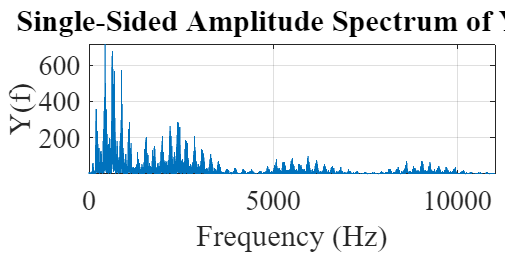


L = length(y1);
Y1 = fft(y1);
y1_fft = fftshift(Y1);
y1_ffts = y1_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(y1_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of Yh(f)', ...
    'Frequency (Hz)', 'Y(f)');
hold off

The function audiowrite() is employed to save the modified audio data into a file named "preamble-reverb.wav". The output signal y1 is written to the file using the specified sample rate Fs.

filename = 'preamble-reverb.wav';
audiowrite(filename,y1,Fs);

Repeating all the previous steps to implement a system that eliminates the distortion caused by the system h[n], the process is carried out below. The resulting approximation error is also calculated.

H = fft(h);
W = 1./H;
w = ifft(W);

fig = figure; clf

plot(w); hold on
grid on
plotlatex(fig,'w[n]', 'Samples (n)', ' ');
hold off

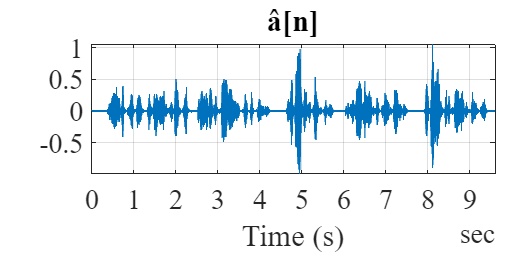


[y,Fs] = audioread("preamble-reverb.wav");

t = 0:seconds(1/Fs):seconds(length(x)/Fs);
t = t(1:end-1);

a_est = conv(y,w);
La = length(a_est)-length(y);
a_est = a_est(La+1:end);

fig = figure; clf

plot(t,a_est); hold on
grid on
plotlatex(fig,'â[n]', 'Time (s)', ' ');
hold off

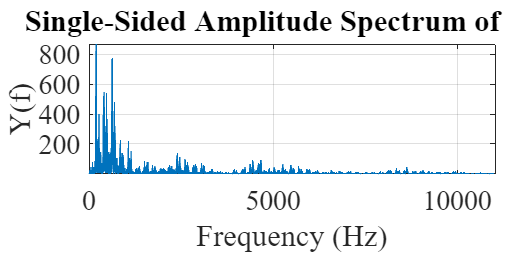


L = length(a_est);
A_fft = fft(a_est);
a_est_fft = fftshift(A_fft);
a_est_ffts = a_est_fft(L/2:L-1);
f = Fs*(0:L/2-1)/L;

fig = figure; clf

plot(f,abs(a_est_ffts)); hold on
grid on
plotlatex(fig,'Single-Sided Amplitude Spectrum of Â(f)', ...
    'Frequency (Hz)', 'Y(f)');
hold off


err = (abs(a_est-x)).^2;

mean(err)

ans = 0.0084

var(err)

ans = 0.0015

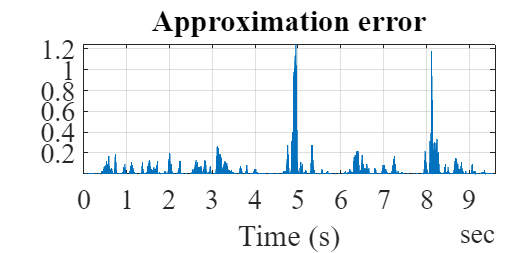


fig = figure; clf

plot(t,err); hold on
grid on
plotlatex(fig,'Approximation error', 'Time (s)', ' ');
hold off

As observed in the previous scenario, despite strictly following the definition to implement an inverse system to eliminate the distortion caused by h[n], the signal response of the equalizer system when the input signal was "preamble-reverb" perfectly estimated the original "preamble" signal. 

Furthermore, the time-domain signal and overall shape of the frequency response exhibited some similarities to the original signal. The mean and variance values of the approximation error were approximately two decimal places, indicating a relatively small error in the estimation.